# Fixed Manipulator

## Geometric model

robot_angles = [0 0 0 0 0 0 0];
[T, A01, A12, A23, A34, A45, A56, A67] = GeometricPanda(robot_angles)

T =     1.0000         0         0    0.0880
         0   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000    0.9260
         0         0         0    1.0000


A01 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


A12 =     1.0000         0         0         0
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.3330
         0         0         0    1.0000


A23 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


A34 =     1.0000         0         0    0.0825
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    0.3160
         0         0         0    1.0000


A45 =     1.0000         0         0   -0.0825
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


A56 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000    0.3840
         0         0         0    1.0000


A67 =     1.0000         0         0    0.0880
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


## Differential Analitic model

[x,R,J] = kinmodel_panda(robot_angles)

x =     0.0880
         0
    0.9260


R =      1     0     0
     0    -1     0
     0     0    -1


J =          0    0.5930         0   -0.2770         0    0.1070         0
    0.0880         0    0.0880         0    0.0880         0         0
         0   -0.0880         0    0.0055         0    0.0880         0
         0         0         0         0         0         0         0
         0    1.0000         0   -1.0000         0   -1.0000         0
    1.0000         0    1.0000         0    1.0000         0   -1.0000


## Robot toolbox DH

dhparams = [0 0.333 0 0 ;
                0 0 -pi/2 0 ;
                0 0.316 pi/2 0 ; 
                0.0825 0 pi/2 0 ;
                -0.0825 0.384 -pi/2 0 ;
                0 0 pi/2 0 ;
                0.088 0 pi/2 0 
                0 0.107 0 0]

dhparams =          0    0.3330         0         0
         0         0   -1.5708         0
         0    0.3160    1.5708         0
    0.0825         0    1.5708         0
   -0.0825    0.3840   -1.5708         0
         0         0    1.5708         0
    0.0880         0    1.5708         0
         0    0.1070         0         0


dhparams = []
robot = rigidBodyTree;
bodies = cell(6,1);
joints = cell(6,1);
for i = 1:6
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name)
    end
end

showdetails(robot)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


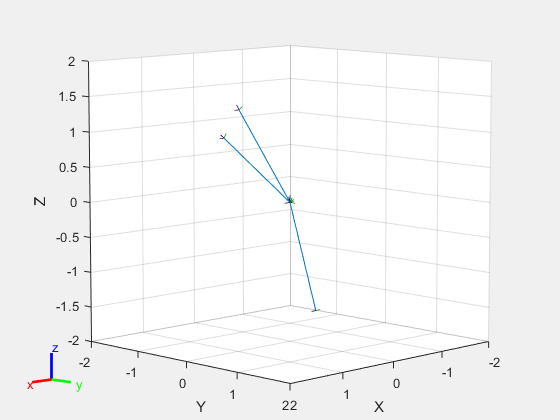

figure(Name="PUMA Robot Model") STOLPCCI SO ZAMEŠANI
show(robot);